alpha = 1 + mod(276,3);
Define the length of the window
N = 64;

rectangular_window = ones(1, N);
hamming_window = hamming(N);
hanning_window = hanning(N);

window_length = 64;
rectangular_window = ones(1, window_length);

% Plot rectangular window
figure;
plot(rectangular_window);
title('Rectangular Window');
xlabel('Sample');
ylabel('Amplitude');

window_length = 64;
hamming_window = hamming(window_length);

% Plot Hamming window
figure;
plot(hamming_window);
title('Hamming Window');
xlabel('Sample');
ylabel('Amplitude');

window_length = 64;
hanning_window = hann(window_length);

% Plot Hanning window
figure;
plot(hanning_window);
title('Hanning Window');
xlabel('Sample');
ylabel('Amplitude');


% Frequency response using freqz
figure;
freqz(rectangular_window, 1, 1024, 1);
title('Rectangular Window');
sgtitle('Frequency Response of Rectangular Window');

figure;
freqz(hamming_window, 1, 1024, 1);
title('Hamming Window');
sgtitle('Frequency Response of Hamming Window');

figure;
freqz(hanning_window, 1, 1024, 1);
title('Hanning Window');

sgtitle('Frequency Response of Hanning Window');



# Problem - 1}


N_values = [100, 200, 300];

N_DFT = 1024;

freq_axis = (0:N_DFT-1) / N_DFT;

for N = N_values
    %  Hanning window
    hanning_window = hann(N);

    t = 0:1/N:(N-1)/N;
    signal = alpha * cos(2 * pi * 0.1 * t);

    % Hanning window
    windowed_signal = signal .* hanning_window;

    % DFT of windowed signal
    dft = fft(windowed_signal, N_DFT);

    % Normalize magnitude by actual length
    normalized_magnitude = abs(dft) / N;

    % Plot
    plot(freq_axis, 20*log10(normalized_magnitude));
    hold on;
end

title('Magnitude Spectrum of Hanning-Windowed Signal');
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');
legend('N=100','N=200','N=300');

grid on;
hold off;


# Problem - 2}

alpha = 1; % hanning window
window_length = 21;
cutoff_frequency = pi / (alpha + 1);

% FIR filters
rectangular_filter = fir1(window_length-1, cutoff_frequency/(pi), 'low', rectwin(window_length));
hanning_filter = fir1(window_length-1, cutoff_frequency/(pi), 'low', hann(window_length));

% Impulse responses
figure;
stem(rectangular_filter, 'b', 'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', 'b');
hold on;
stem(hanning_filter, 'r', 'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', 'r');
hold off;
title('Impulse Response of Low-Pass FIR Filters');
xlabel('Sample Index');
ylabel('Amplitude');
legend('Rectangular Window', 'hamming Window');
grid on;

% Frequency responses 
[frequency_response_rect, freq_rect] = freqz(rectangular_filter, 1, 'half');
[frequency_response_hanning, freq_hanning] = freqz(hanning_filter, 1, 'half');

figure;
plot(freq_rect, 20*log10(abs(frequency_response_rect)), 'b', 'LineWidth', 1.5);
hold on;
plot(freq_hanning, 20*log10(abs(frequency_response_hanning)), 'r', 'LineWidth', 1.5);
hold off;
title('Frequency Response (Bode Plot) of Low-Pass FIR Filters');
xlabel('Frequency (\pi radians/sample)');
ylabel('Magnitude (dB)');
legend('Rectangular Window', 'Hanning Window');
grid on;




# Problem - 3}

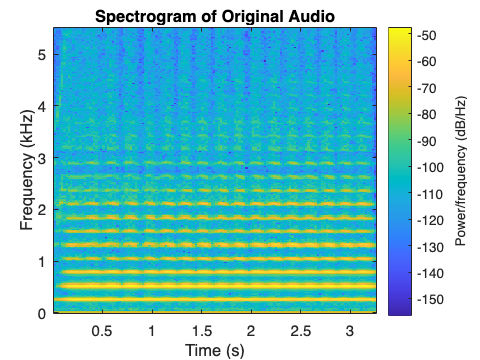


[y, fs] = audioread('instru1.wav');
% Compute the DFT of the audio signal
N = length(y);
dft = fft(y, N);

figure
spectrogram(y,hanning(512),256,512,fs, 'yaxis');
title('Spectrogram of Original Audio');


% Magnitude spectrum of DFT
magnitude_spectrum = abs(dft);
% Fundamental frequency
[~, peak_index] = max(magnitude_spectrum(2:end));
fundamental_frequency = peak_index * fs / N

fundamental_frequency = 524.3338

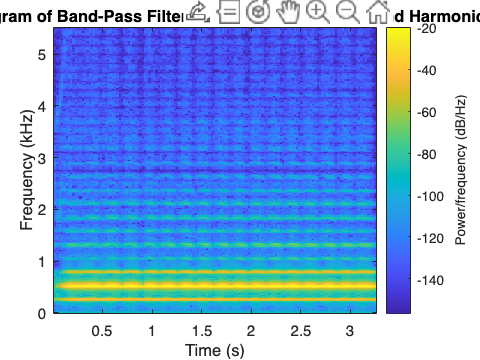


low_cutoff = fundamental_frequency - 20; 
high_cutoff = fundamental_frequency + 20; 

% Normalize cutoff frequencies to Nyquist rate
nyquist_freq = fs / 2;
low_cutoff_normalized = low_cutoff / nyquist_freq;
high_cutoff_normalized = high_cutoff / nyquist_freq;

filter_order = 63;
filter_coefficients = fir1(filter_order, [low_cutoff_normalized, high_cutoff_normalized], 'bandpass', hamming(filter_order + 1));

% FIR filter
filtered_audio = filter(filter_coefficients, 1, y);

filtered_audio = filtered_audio / max(abs(filtered_audio));

audiowrite('filtered_instru_bandpass.wav', filtered_audio, fs);

sound(filtered_audio, fs);

% Spectogram
figure;
spectrogram(filtered_audio, hann(512), 256, 512, fs, 'yaxis');
title('Spectrogram of Band-Pass Filtered Audio (Fundamental and Harmonics)');